# Standard Layers Analysis of a DSPC Floating Bilayer

In this worksheet, we will carry out an analysis of a floating bilayer sample using a 'standard layers' model. 

The sample consists of a DSPC bilayer, on a silane SAM on Silicon as follows.....

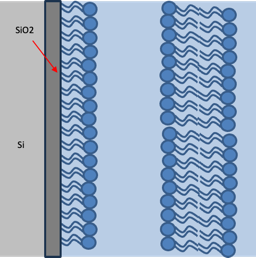

So we are going to need layers for Oxide, SAM tails, SAM heads, and the Heads/Tails of the Bilayer. We also need to consider hydration of the submerged bilayer.

Start by making a project....

% Make the project
problem = createProject(name='original_dspc_bilayer', calcType='non polarised', model='standard layers', geometry='substrate/liquid', absorption=false);

% Make priors visible..
problem.setUsePriors(true);

The add the parameters we are going to need to this....

paramGroup = {
              {'Oxide thick',           5,      19.54,      60,     true,   'uniform',      0,  Inf};
              {'Oxide SLD',         3.39e-06,   3.39e-06, 3.41e-06, false,  'uniform',      0,  Inf};
              {'Sam tails thick',       15,     22.66,      35,     true,   'uniform',      0,  Inf};
              {'Sam tails SLD',         -5e-07, -4.01e-07, -3e-07,  false,  'uniform',      0,  Inf};
              {'Sam tails hydration',   1,      5.253,      50,     true,   'uniform',      0,  Inf};
              {'Sam rough',             1,      5.64,       15,     true,   'uniform',      0,  Inf};
              {'cw thick',              10,     17.12,      28,     true,   'uniform',      0,  Inf};
              {'cw SLD',                0,      0,          1e-09,  false,  'uniform',      0,  Inf};
              {'SAM head thick',        5,      8.56,       17,     true,   'gaussian',    10,    2};
              {'SAM head SLD',          1e-07,  1.75e-06,   2e-06,  false,  'uniform',      0,  Inf};
              {'SAM head hydration',    10,     45.45,      50,     true,   'uniform',     30,    3};
              {'Bilayer head thick',    7,      10.70,      17,     true,   'gaussian',    10,    2};
              {'Bilayer head SLD',      5e-07,  1.47e-06, 1.5e-06,  false,  'uniform',      0,  Inf};
              {'Bilayer rough',         2,      6.014,      15,     true,   'uniform',      0,  Inf};
              {'Bilayer tails thick',   14,     17.82,      22,     true,   'uniform',      0,  Inf};
              {'Bilayer tails SLD',     -5e-07, -4.610e-07, 0,      false,  'uniform',      0,  Inf};
              {'Bilayer tails hydr',    10,     17.64,      50,     true,   'uniform',      0,  Inf};
              {'Bilayer heads hydr',    10,     36.15,      50,     true,   'gaussian',    30,    3};
              {'cw hydration',          99.9,   100,        100,    false,  'uniform',      0,  Inf};
              {'Oxide Hydration',       0,      23.61,      60,     true,   'uniform',      0,  Inf};
              };
problem.addParameterGroup(paramGroup);

% In addition to these, there is also Substrate Roughness which is always
% parameter 1. Increase the allowed range of this a bit....
problem.setParameter(1,'max',10);

Now we can group these parameters into the layers we need, and add them to the project......

% Group these into layers....
Layers =    {
            {'Oxide',           'Oxide thick',          'Oxide SLD',        'substrate roughness',  'Oxide Hydration',      'bulk out'};
            {'Sam tails',       'Sam tails thick',      'Sam tails SLD',    'Sam rough',            'Sam tails hydration',  'bulk out'};
            {'Sam heads',       'SAM head thick',       'SAM head SLD',     'Sam rough',            'SAM head hydration',   'bulk out'};
            {'Central water',   'cw thick',             'cw SLD',           'Bilayer rough',        'cw hydration',         'bulk out'};
            {'Bilayer heads',   'Bilayer head thick',   'Bilayer head SLD', 'Bilayer rough',        'Bilayer heads hydr',   'bulk out'};
            {'Bilayer tails',   'Bilayer tails thick',  'Bilayer tails SLD','Bilayer rough',        'Bilayer tails hydr',   'bulk out'};
};
problem.addLayerGroup(Layers);

Now deal with the experimental params. We need a bulk in of Silicon, and two Bulk outs - D2O and SMW

% Remove the existing default first (we could just rename it and change the
% values, of course....)
problem.removeBulkIn(1);
problem.addBulkIn('Silicon', 2e-06, 2.073e-06, 2.1e-06, false);

%.... ditto bulk out....
problem.removeBulkOut(1);
problem.addBulkOut('D2O', 5.50e-06, 5.98e-06, 6.4e-06, true);
problem.addBulkOut('SMW', 1e-06, 2.21e-06, 4.99e-06, true);

Likewise the scalefactors and backgrounds......

% Set the scalefactors - use one for each contrast
problem.removeScalefactor(1);
problem.addScalefactor('Scalefactor 1', 0.05, 0.10, 0.2, true);
problem.addScalefactor('Scalefactor 2', 0.05, 0.15, 0.2, true);

% Now deal with the backgrounds....
problem.removeBackgroundParam(1);
problem.addBackgroundParam('Backs parameter D2O', 5e-10, 2.23e-06, 7e-06,      true);
problem.addBackgroundParam('Backs parameter SMW', 1e-10, 3.38e-06, 4.99e-06,   true);

problem.removeBackground(1);
problem.addBackground('D2O Background','constant','Backs parameter D2O');
problem.addBackground('SMW Background','constant','Backs parameter SMW');

Now load in and add the data....

d2o_dat = readmatrix('DSPC_D2O.dat');
problem.addData('dspc_bil_d2O', d2o_dat);

smw_dat = readmatrix('DSPC_SMW.dat');
problem.addData('dspc_bil_smw', smw_dat);

Finally, we build everything up into the two contrasts.....

problem.addContrast('name',         'D2O',...
                    'BulkIn',       'Silicon',...
                    'BulkOut',      'D2O',...
                    'background',   'D2O Background',...
                    'resolution',   'Resolution 1',... 
                    'scalefactor',  'Scalefactor 1',...
                    'data',         'dspc_bil_d2o');

problem.addContrast('name',         'SMW',...
                    'BulkIn',       'Silicon',...
                    'BulkOut',      'SMW',...
                    'background',   'SMW Background',...
                    'resolution',   'Resolution 1',... 
                    'scalefactor',  'Scalefactor 2',...
                    'data',         'dspc_bil_smw');

...and add the relevant layers to each contrast.......

stack =  {'Oxide',...
          'Sam tails',...
          'Sam heads',...
          'Central water',...
          'Bilayer heads',... 
          'Bilayer tails',...
          'Bilayer tails',... 
          'Bilayer heads',...
          };

problem.setContrastModel(1,stack);
problem.setContrastModel(2,stack);

Display our project, to check what we have....

% Just the name of the project with no semicolon.....
problem

problem =          modelType: 'standard layers'
    experimentName: 'original_dspc_bilayer'
          geometry: 'substrate/liquid'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p             Name               Min         Value        Max       Fit?     Prior Type    mu    sigma
    __    _____________________    ________    _________    ________    _____    __________    __    _____

     1    "Substrate Roughness"           1            3          10    true     "uniform"      0     Inf 
     2    "Oxide thick"                   5        19.54          60    true     "uniform"      0     Inf 
     3    "Oxide SL

## Running the Project....

To run a project in RAT, we first need to define a controls block....

controls = controlsClass()

controls =   controlsClass with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 0
             display: 'iter'
           resamPars: [0.9000 50]


The devaults action ('procedure') is just a single caclulation. So send out project to RAT with this, and then plot our our initial starting position...

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.001670 seconds.

Finished RAT ______________________________________________________________________________________________ 



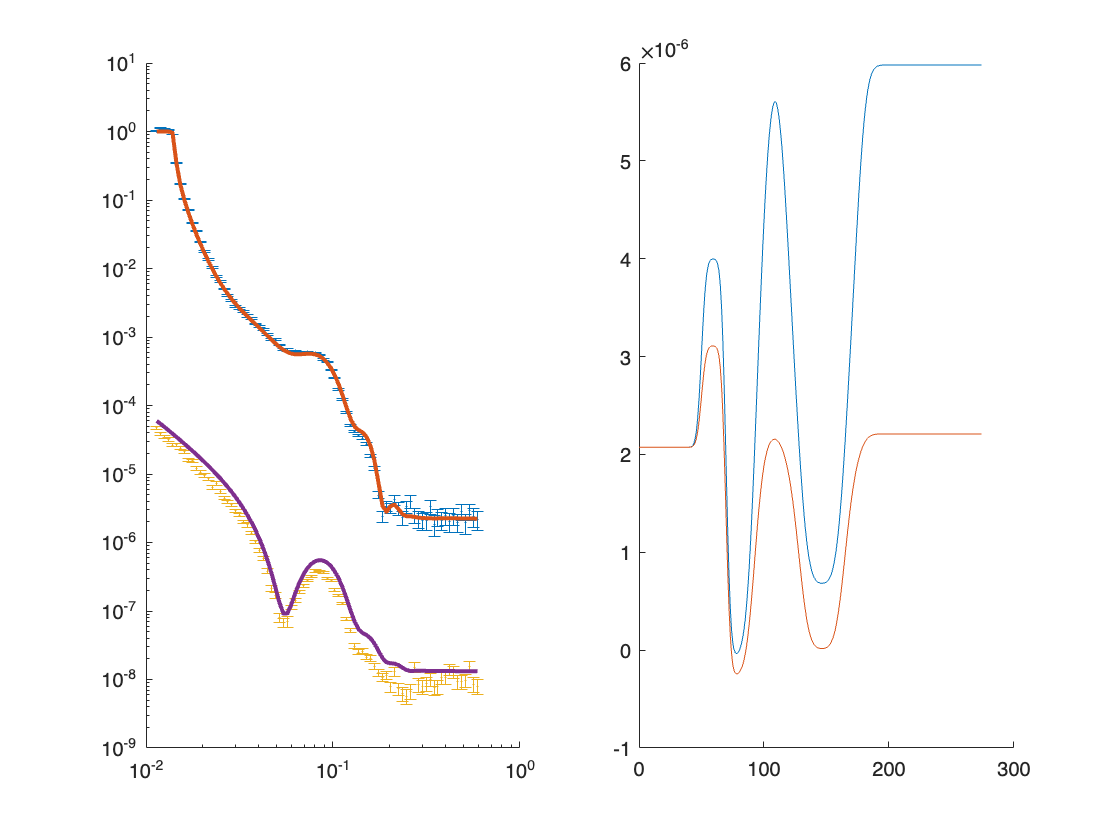

figure
plotRefSLD(problem,results);

We are as expected, a little off. Run some Differential Evolution on this.....

controls.procedure = 'DE';
controls.display = 'final'  % Turn off per-iteration updates....

controls =   controlsClass with properties:

                parallel: 'single'
               procedure: 'de'
        calcSldDuringFit: 0
                 display: 'final'
          populationSize: 20
                 fWeight: 0.5000
    crossoverProbability: 0.8000
                strategy: 4
             targetValue: 1
          numGenerations: 500
               resamPars: [0.9000 50]


Note that now, the relevant parameters for Differential Evoultion appear in Controls. We can change these at this point if we want (e.g. controls.populationSize = 50 etc), but we'll go with the defaults for now....

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 7.9574
Elapsed time is 2.564720 seconds.

Finished RAT ______________________________________________________________________________________________ 



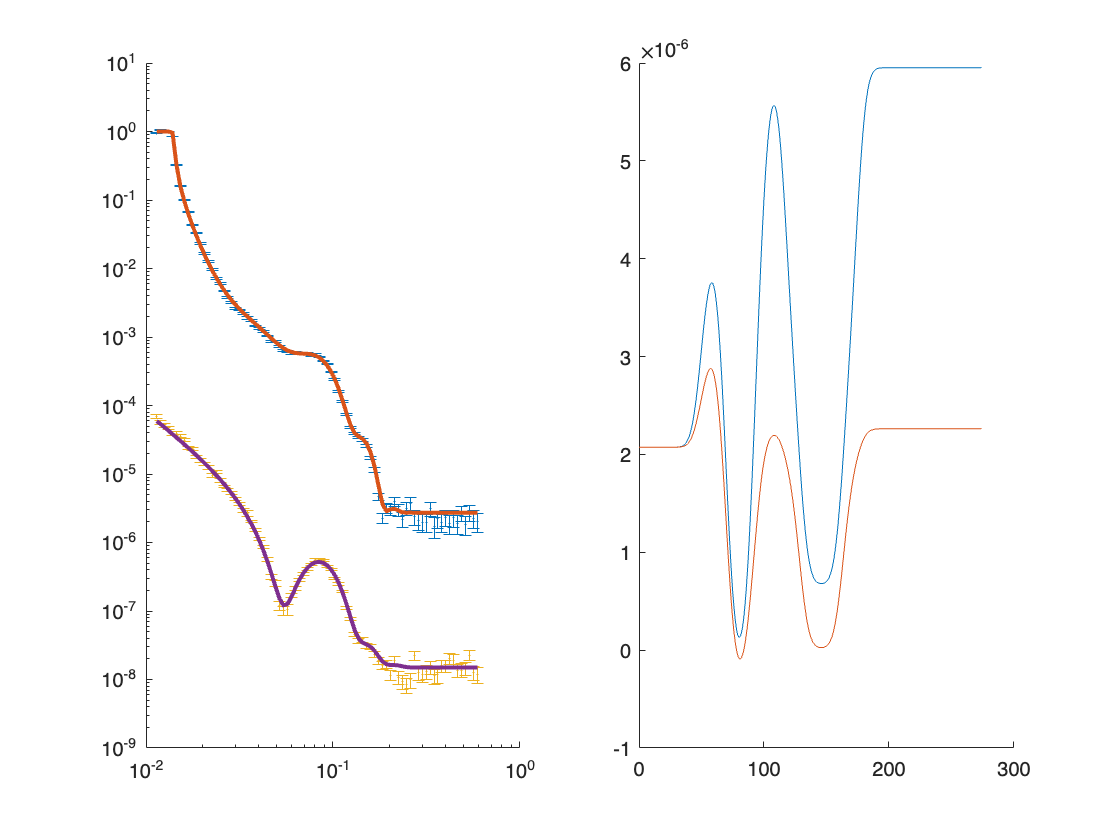

figure
plotRefSLD(problem,results)

This is decent starting point, but we really want a Bayesian analysis. To do this just select DREAM in controls.....

controls.procedure = 'dream'

controls =   controlsClass with properties:

            parallel: 'single'
           procedure: 'dream'
    calcSldDuringFit: 0
             display: 'final'
           resamPars: [0.9000 50]
            nSamples: 50000
             nChains: 10
     jumpProbability: 0.5000
          pUnitGamma: 0.2000
       boundHandling: 'fold'
            adaptPCR: 0


Again we'll just go with the defaults.....

[problem,results] = RAT(problem,controls)

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 20
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.5000
    pUnitGamma: 0.2000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.0000e-12
       outlier: 'iqr'
      adaptPCR: 0
      thinning: 1
       epsilon: 0.0250
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:  100.0% [****************************************]
Elapsed time is 21.072961 seconds.

Finished RAT ______________________________________________________________________________________________ 



problem =          modelType: 'standard layers'
    experimentName: 'original_dspc_bilayer'
          geometry: 'substrate/liquid'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p             Name               Min         Value        Max       Fit?     Prior Type    mu    sigma
    __    _____________________    ________    _________    ________    _____    __________    __    _____

     1    "Substrate Roughness"           1       4.5095          10    true     "uniform"      0     Inf 
     2    "Oxide thick"                   5       18.849          60    true     "uniform"      0     Inf 
     3    "Oxide SL

results = struct with fields:
          reflectivity: {2×1 cell}
            Simulation: {2×1 cell}
          shifted_data: {2×1 cell}
             layerSlds: {2×1 cell}
           sldProfiles: {2×1 cell}
             allLayers: {2×1 cell}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]
           bestFitPars: [4.5095 18.8488 22.8579 10.1331 4.7736 17.7893 9.8851 31.8187 9.8927 6.2494 17.7699 17.9402 30.1826 21.6341 2.3042e-06 2.8092e-06 0.1048 0.1048 5.9666e-06 2.1856e-06]
          bestFitsMean: [1×1 struct]
              predlims: [1×1 struct]
           parConfInts: [1×1 struct]
              bestPars: [4.5095 18.8488 22.8579 10.1331 4.7736 17.7893 9.8851 31.8187 9.8927 6.2494 17.7699 17.9402 30.1826 21.6341 2.3042e-06 2.8092e-06 0.1048 0.1048 5.9666e-06 2.1856e-06]
              bayesRes: [1×1 struct]
                 chain: [37510×20 double]
              fitNames: {20×1 cell}


Finally, plot out what we have....

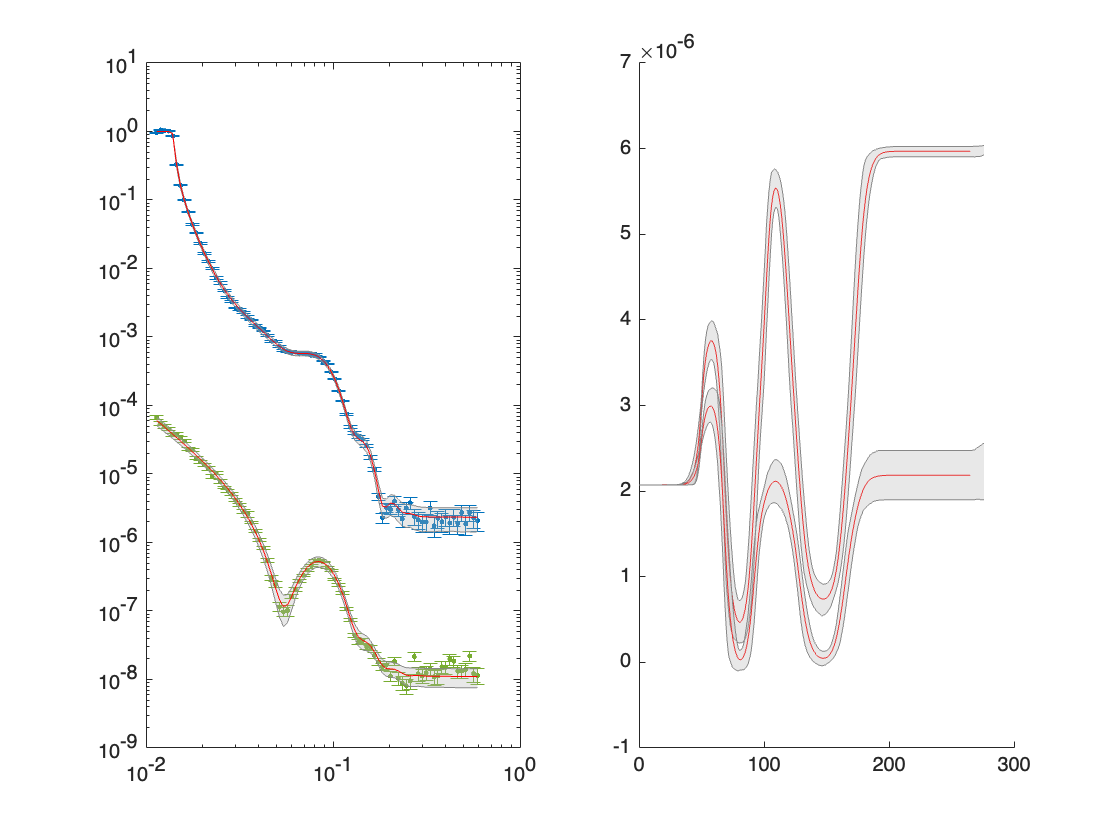

h1 = figure;    
bayesShadedPlot(problem, results,'fit','average','KeepAxes',true,'interval',65,'q4',false)

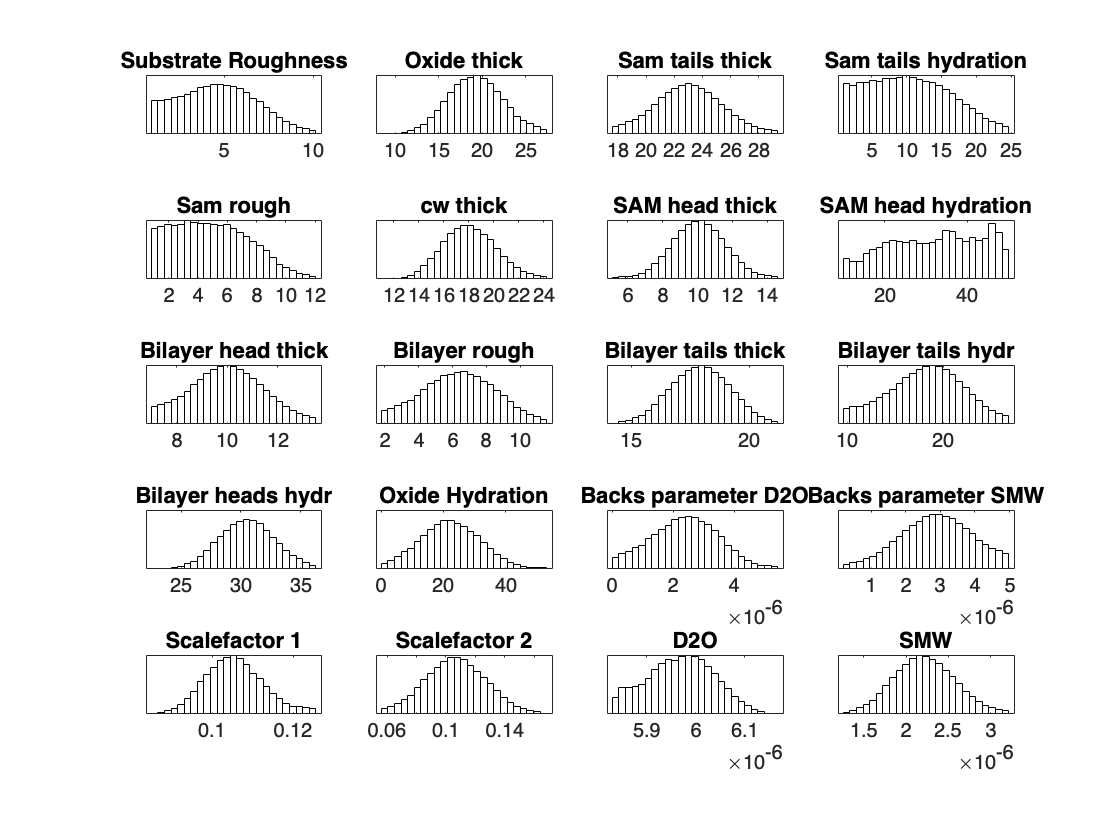

ans =   Axes (SMW) with properties:

             XLim: [1.1976e-06 3.2724e-06]
             YLim: [0 1.1097e+06]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7484 0.1100 0.1566 0.1243]
            Units: 'normalized'

  Show all properties



h3 = figure;
plotHists(results,h3,'smooth',true)

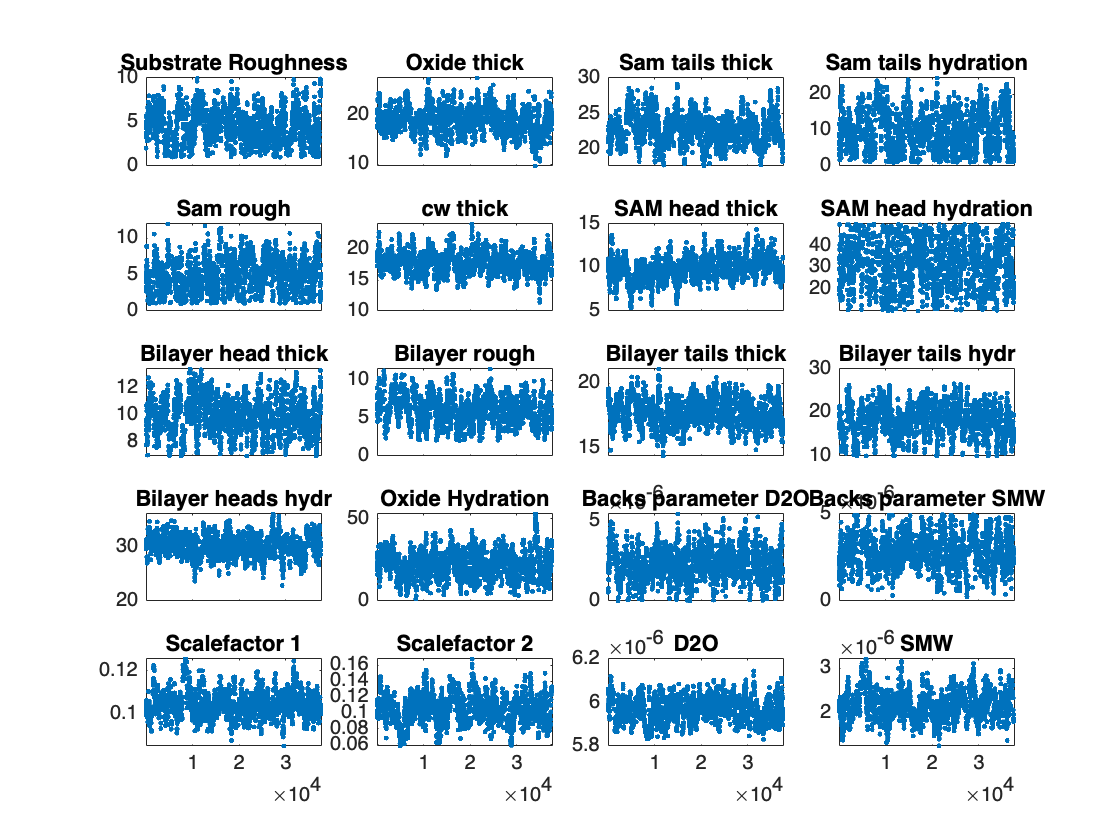


figure
mcmcplot(results.chain,[],results.fitNames,'chainpanel');

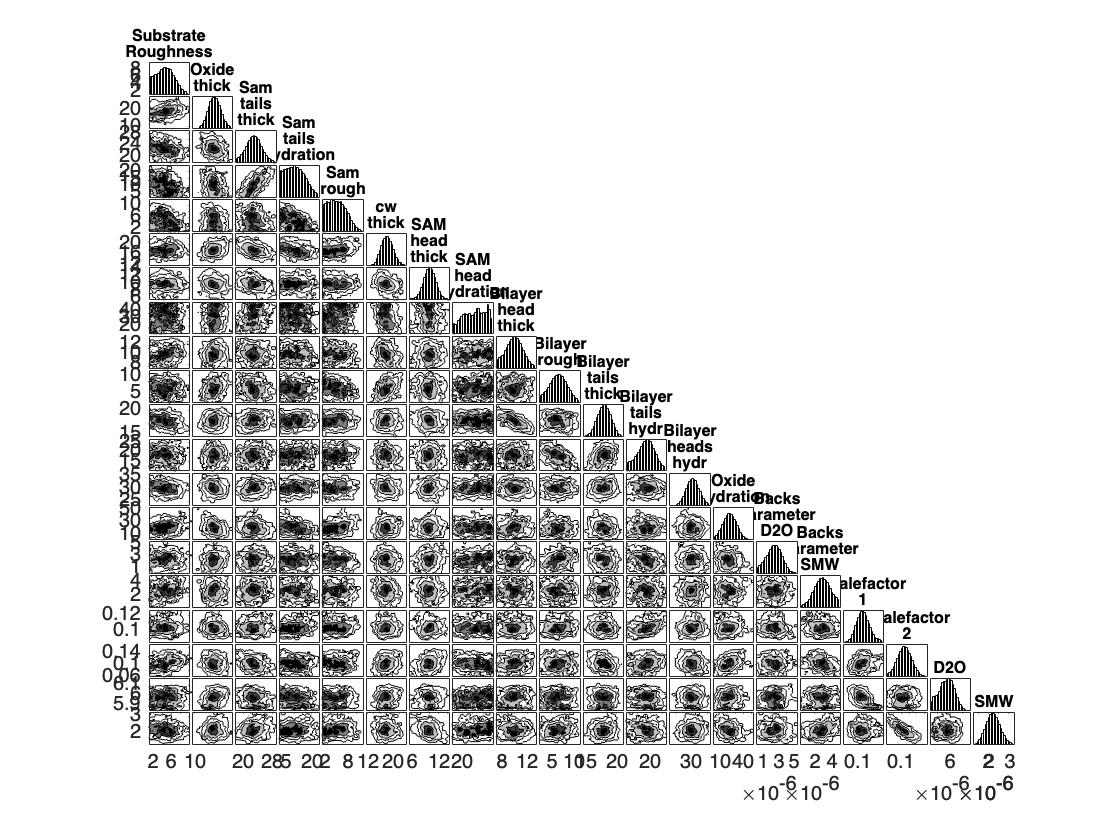


h4 = figure;    % Need a figure handle....
cornerPlot(results,h4,'smooth',false)